## **Przetwarzanie Sygnałów Cyfrowych**

# Cakowe przeksztacenie fouriera

## Jan Rosa 410269 AiR

## Ćwiczenie 1

Transformata fouriera sygnału sin(wt)

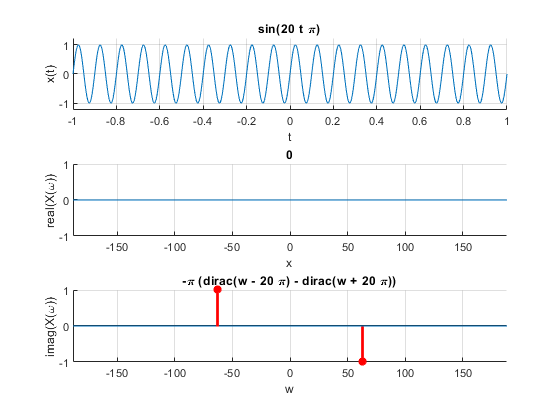

syms t
f0 = 10; %Hz
w0 = 2*pi*f0;
x = sin(w0*t);
fourT_dirac(x, f0)

## Zad 2

### a) sygnaª cos(ω0t)

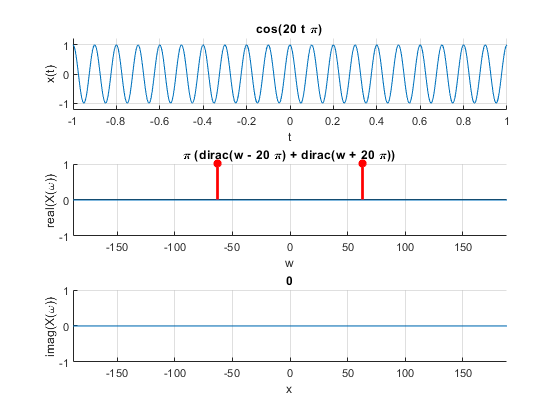

f0 = 10; %Hz
w0 = 2*pi*f0;
x = cos(w0*t);
fourT_dirac(x, f0)

### b) sygnaª staªy o warto±ci 10 (do jego zde�niowanie nale»y u»y¢ polecenia sym(10))

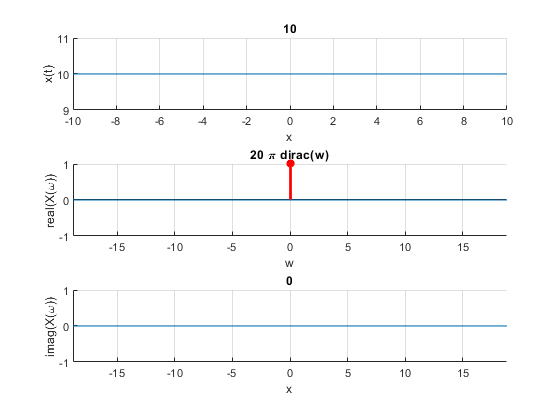

f0 = 1; %Hz
x = sym(10);
fourT_dirac(x, f0)

### c) skok jednostkowy o amplitudzie 1

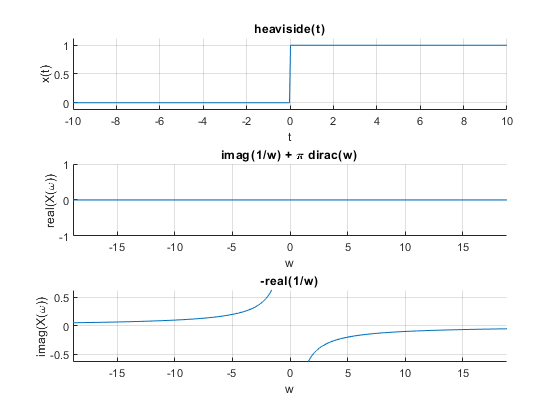

f0 = 1; %Hz
x = heaviside(t);
fourT_cont(x, f0)

### d) impuls prostok¡tny o amplitudzie 1 oraz czasie trwania Ti = 2/f0

f0 = 2;
x = rectangularPulse(-1, 1, t)

$$x = \mathrm{rectangularPulse}\left(-1,1,t\right)$$

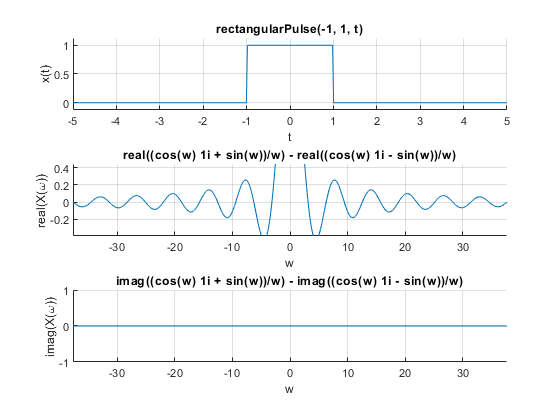

fourT_cont(x, f0)

### e) impuls trójkątny (symetryczny) o amplitudzie 1 oraz czasie trwania Ti = 2/f0 .

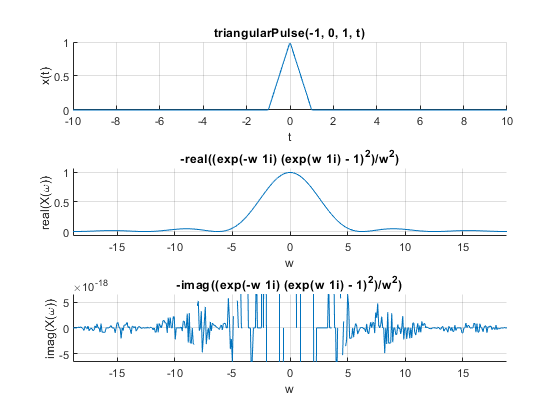

f0 = 1;
x = triangularPulse(-1/f0, 1/f0, t);
fourT_cont(x, f0)

### ZD2

Dla przebiegów cos(ω0t) oraz sin(ω0t) sporz¡d¹ równie» wykresy g¦sto±ci widmowej amplitudy oraz fazy. Porównaj je i opisz ró»nice w sprawozdaniu.

#### Cos

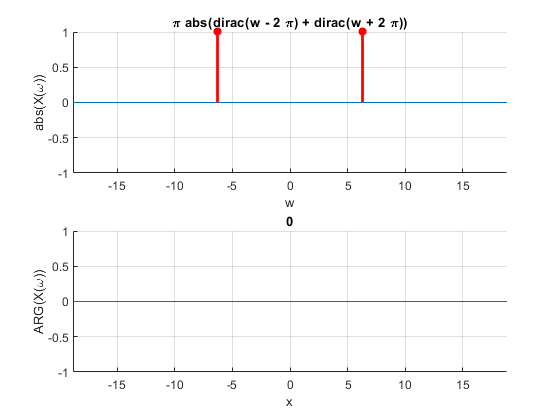

syms w t
f0=1;
w0 = 2*pi* f0;
x = cos(w0*t);

fourT_dirac_gestosc(x, f0)

#### Sin

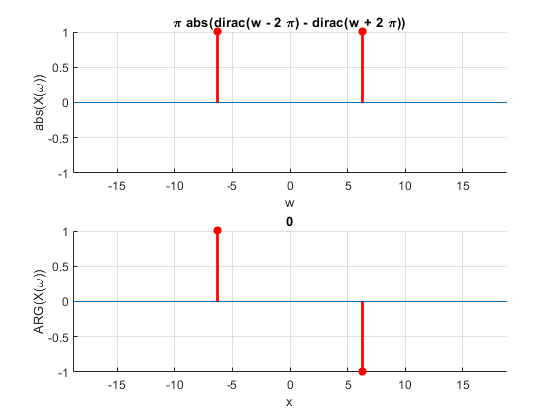

syms w t
f0=1;
w0 = 2*pi* f0;
x = sin(w0*t);

fourT_dirac_gestosc(x, f0)

Sin i cos posiadają takie same amplitudy, cos ma fazę zerową a sin niezerową.

## Zadanie 3

Przeprowad¹ modulacj¦ sygnaªu cos(ω0t) przebiegiem sinusoidalnym o cz¦stotliwo±ci 10-krotnie mniejszej, amplitudzie 1 i gª¦boko±ci modulacji m = 0.5. Wyznacz transformat¦ Fouriera sygnaªu zmodulowanego i uzgodnij skal¦ pr¡»ków widma. Kod programu oraz wykresy samie±¢ w sprawozdaniu

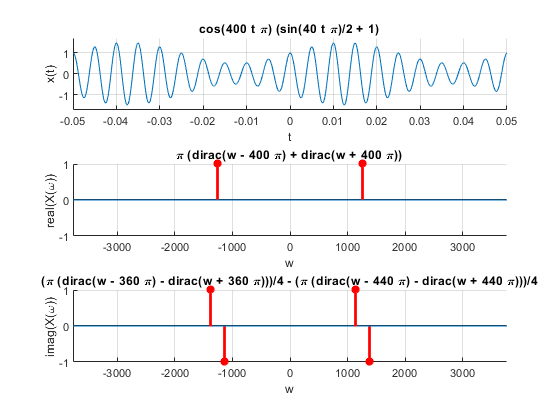

syms t
f0 = 20;
f1 = 200;
w0 = 2*pi*f0;
w1 = 2*pi*f1;
%modulacja amplitudowa
m = 0.5;
x = cos(w1*t) * (1 + m*sin(w0*t));
fourT_dirac(x, f1);

### ZD3

Porównaj moc sygnaªu no±nego z moc¡ wynikowego sygnaªu zmodulowanego. Napisz w sprawozdaniu jaki wpªyw na t¦ relacj¦ ma gª¦boko±¢ modulacji m. \

syms t w
m_v = 0:0.1:1;
power_v = m_v;
i = 1;

%figure
for m = m_v
    x = cos(w0*t)*(1 + m*sin(w1*t));
    xp = x^2;
    px = 1/w1 * int(xp, t, 0 , 1/f0);
    pxd = double(px);
    power_v(i) = pxd;
    i = i + 1;
    %hold on 
    %fplot(t,x,[-1,1])
end

figure
plot(m_v,power_v); grid on;

Moc zwiększa się wyykładniczo do około 150% wartości mocy sygnału niezmodulowanego

## Zad 4

Wyznacz transformat¦ Fouriera sygnaªu cos(!0t) "okienkowanego" tak aby w oknie znajdowa

ªo si¦ 6.5 okresów przebiegu To = 6:5=f0. Dzi¦ki temu, przebieg rozpocznie si¦

w obr¦bie okna i zako«czy warto±ci¡ si¦ warto±ci¡ zerow¡. Do okienkowania zastosuj

odpowiednio przeskalowane sygnaªy z Zad. 2:

syms t
f0 = 1

f0 = 1

w0 = 2*pi*f0

w0 = 6.2832

x = cos(w0*t+pi/2);

okienkowanie sygnałem prostokątnym

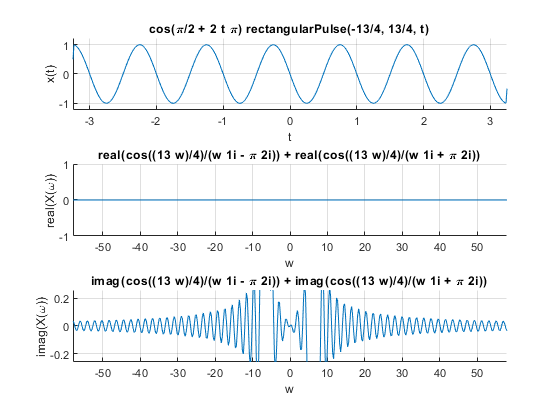

okno = rectangularPulse(-3.25, 3.25, t);
fourT_cont_o(x, okno, 3.25)

okienkowanie sygnałem trójkątnym

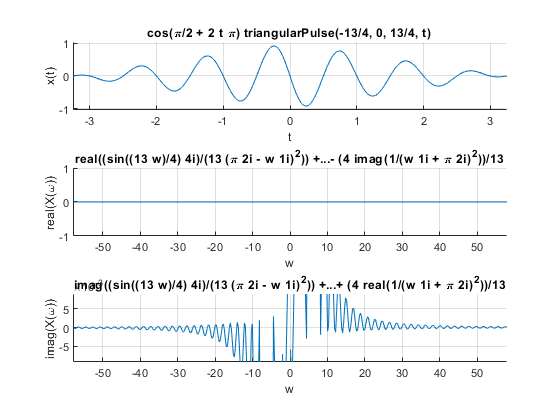

okno = triangularPulse(-3.25, 3.25, t);
fourT_cont_o(x, okno, 3.25)

okienkowanie sygnałem krzywej gaussa

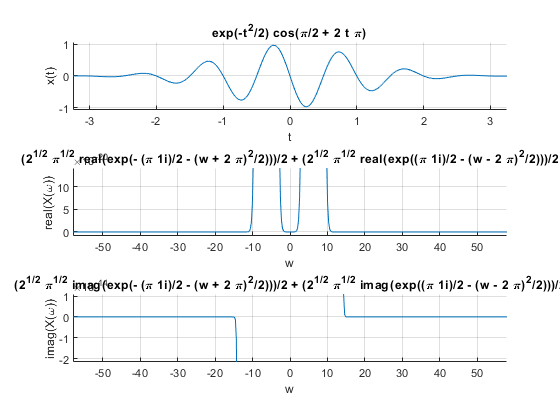

okno = exp((-t^2)/2);
fourT_cont_o(x, okno, 3.25)

## ZD3

Dla ka»dego przypadku sporz¡d¹ wykres g¦sto±ci widmowej am-

plitudy sygnaªu. porównaj uzyskane wyniki z widmem sygnaªu cos(ω0t) niepoddanego

okienkowaniu. Wska» najlepsz¡ metod¦ okienkowania i uzasadnij wybór.

function [] = fourT_dirac(x, f0)

syms w t

w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2)];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2)];
X_FT = fourier(x);

%plot signal
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);



%plot real of fourier
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot imag of fourier
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

end


function [] =fourT_dirac_gestosc(x, f0)

syms w t

w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2)];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2)];
X_FT = fourier(x);

figure
%plot abs of fourier
subplot(2,1,1); ylabel('abs(X(\omega))'); hold on
ezplot(abs(X_FT), BND_w); hold on; grid on
v_num = subs(abs(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot agr of fourier
subplot(2,1,2); ylabel('ARG(X(\omega))'); hold on
ezplot(sym(0), BND_w); hold on; grid on
v_num = subs(angle(X_FT), w, w_SMP);
n = find( abs(v_num) == pi/2 ); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end


function [] =fourT_dirac_o(x, okno, f0)
    y = x * okno;
    fourT_dirac(y, f0)
end


function [] = fourT_cont(x, f0)

syms w t

w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2)];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2)];
X_FT = fourier(x);

%plot signal
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot real of fourier
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;

%plot imag of fourier
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
end

function [] =fourT_cont_o(x, okno, zakres)
    y = x * okno;
    fourT_cont(y, 10/zakres)
end

function [] =fourT_cont_gestosc(x, f0)

syms w t

w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2)];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2)];
X_FT = fourier(x);

figure
%plot abs of fourier
subplot(2,1,1); ylabel('abs(X(\omega))'); hold on
ezplot(abs(X_FT), BND_w); hold on; grid on

%plot arg of fourier
subplot(2,1,2); ylabel('imag(X(\omega))'); hold on
ezplot(angle(X_FT), BND_w); hold on; grid on
end
